clear all;
close all;

path_opt_table= readtable('traj_opt.csv');

s_opt_table= readtable('length_opt.csv');


london_outer_table=readtable('london_outer.csv');

london_inner_table=readtable('london_inner.csv');


xy_ref= [path_opt_table.x_Traj_x, path_opt_table.traj_y];
s_ref= s_opt_table.x_S_opt;

u_steer= deg2rad([-15:0.5:15]);
dt= 0.002;
state_init= [xy_ref(1, 1), xy_ref(1,2) , 0, 0];
run_length= 150;

u_hist= [];
states_hist=[];
v_last= 0;

figure()

for i= 2:run_length
    ds= s_ref(i);
    state0= state_init;
    
    ref_devi= (xy_ref(i,2)- xy_ref(i-1,2))/(xy_ref(i,1)- xy_ref(i-1,1));
    dist_err_list=[];
    cord_err_list=[];
    devi_err_list=[];
    
    % generate path for each steer angle
    
    for j= 1:length(u_steer)
        
        [path_states, path_info, u]= SteerPathGenerator(state_init, dt, u_steer(j), ds, v_last);
        path_states= [state_init; path_states];
        
        path_devi= (path_states(end, 2)- state0(2))/((path_states(end,1)- state0(1)));
        devi_err= abs(path_devi- ref_devi);
        devi_err_list= [devi_err_list; devi_err];
        

%         dist_err= (path_states(:,1)- xy_ref(i, 1)).^2+ (path_states(:,2)- xy_ref(i, 2)).^2;
%         dist_err_sum= sum(dist_err);
%         dist_err_list= [dist_err_list; dist_err_sum];
        
%         cord_err= abs(path_states(end,1)- xy_ref(i,1))+ abs(path_states(end,2)- xy_ref(i,2));
%         cord_err_list= [cord_err_list; cord_err];
        
        % plot(path_states(:,1), path_states(:,2));
        % hold on
    end
    
    path_index= find(devi_err_list== min(devi_err_list));
    [states_passed, path_info_paseed, u_passed]= SteerPathGenerator(state0, dt, u_steer(path_index), ds, v_last);
    
    u_hist= [u_hist; u_passed];
    states_hist= [states_hist; states_passed];
    
    state_init= states_passed(end,:);
    v_last= states_passed(end-1, 4);
end


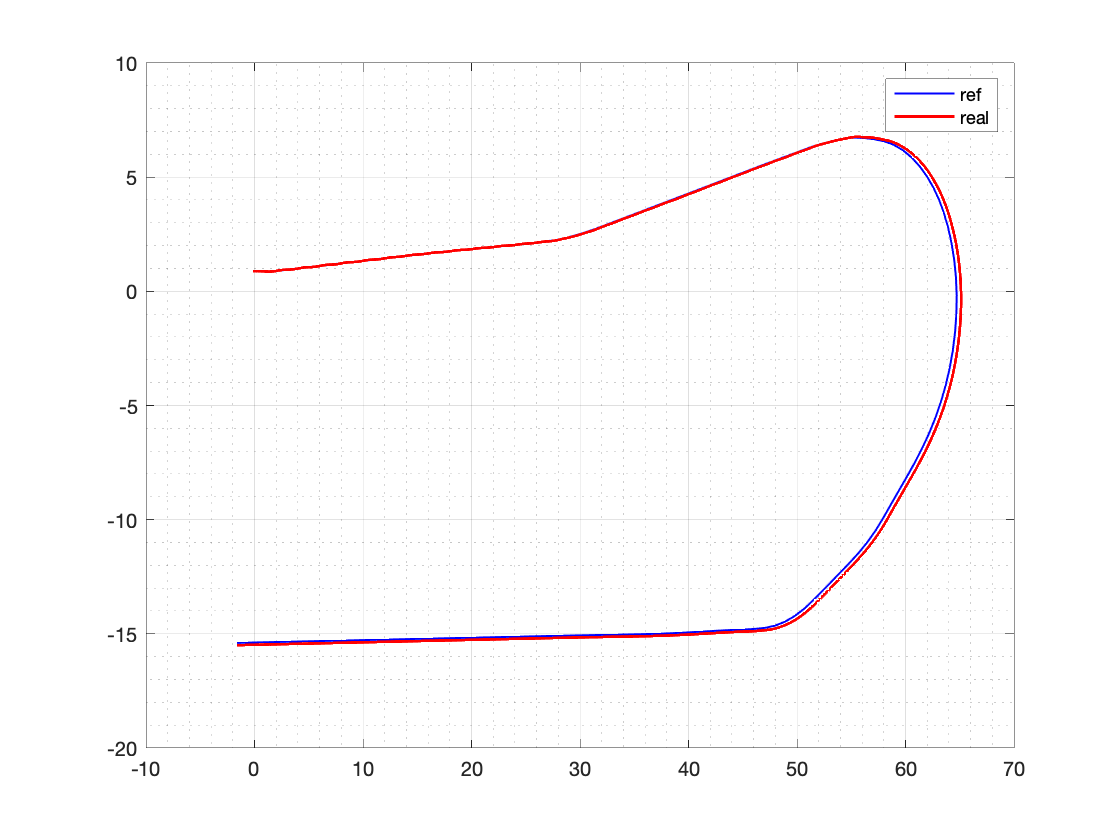

close all;

% path
plot_num= 1:run_length;
figure();
plot(xy_ref(plot_num, 1), xy_ref(plot_num, 2), 'linewidth', 1.0, "Color", 'blue');
hold on;
plot(states_hist(:,1), states_hist(:,2), 'linewidth', 1.5, "Color", 'red');
hold off
grid on; grid minor;
legend('ref', 'real')

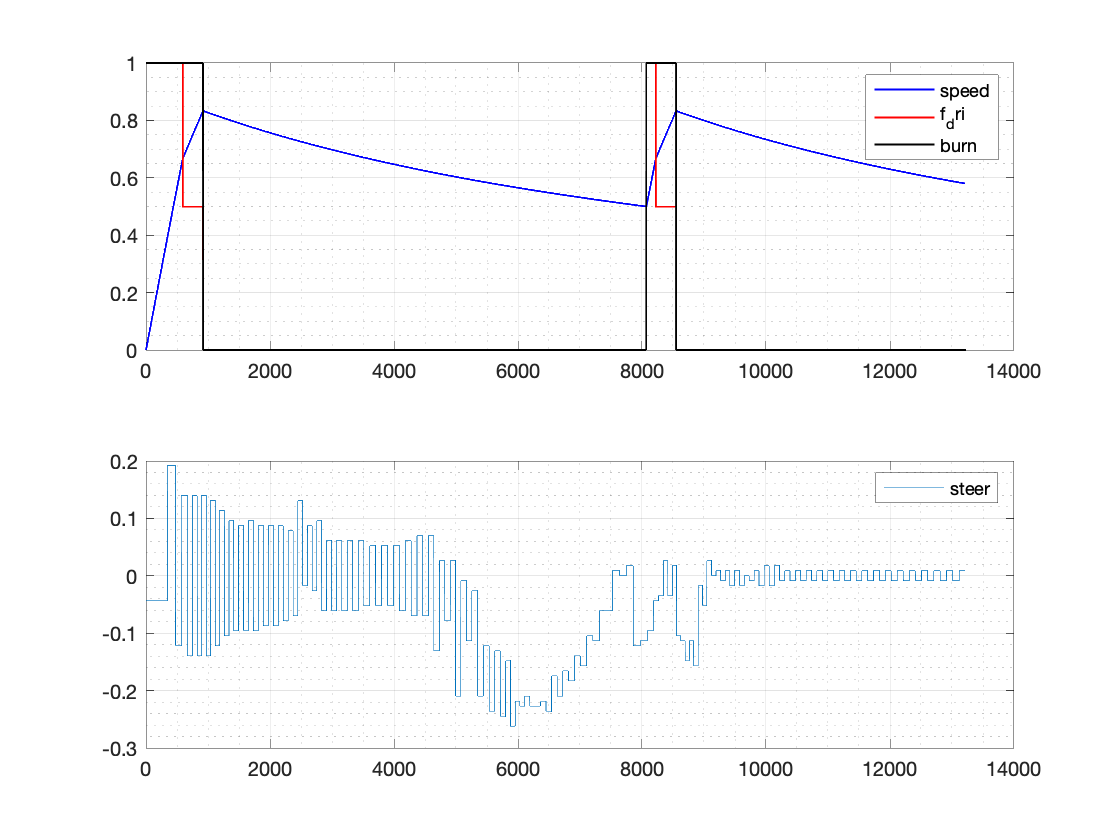



% inputs
figure();
subplot(2,1,1)
plot(states_hist(:,4)/(30/3.6), 'linewidth', 1.0, "Color", 'blue');
hold on;
plot(u_hist(:,1), 'linewidth', 1.0, "Color", 'red');
hold on;
plot(u_hist(:,2), 'linewidth', 1.0, "Color", 'black');
hold off;
legend('speed', 'f_{dri}', 'burn');
grid on; grid minor;

subplot(2,1,2);
plot(u_hist(:,3));
legend('steer');
grid on; grid minor;